# **Ejercicio 1**

## T2.1 Búsqueda de raíces 

### 28-02-2023

#### Grupo 8: Ana Robledano Abasolo, Alfredo Robledano Abasolo, 

####                 Melani Tatayo Culchas, Rubén Sierra Serrano.

a) Escribe una función de Matlab para obtener un intervalo de ancho `dx` que 

contenga una raíz de la función 𝑓(𝑥) partiendo de un intervalo (𝑎,𝑏) con 𝑎 < 𝑏 

Nombra a la función: $function   [x1, x2] = raizbus(fun, a, b, dx) $ donde: 

$fun =$ función en forma anónima $fun = @(x) $

$\left(a,b\right)=$ intervalo de inicio de búsqueda 

$\textrm{dx}=$ ancho del intervalo 

$[x1, x2] =$  intervalo de ancho dx donde se encuentra una raíz de 𝑓(𝑥) 

b) Escribe una función de Matlab que obtenga las abscisas de los intervalos 

donde se encuentran todas las raíces de una función 𝑓(𝑥) en un intervalo dado 

(𝑎,𝑏) llamando a la función `raizbus` creada anteriormente. 

Nómbrala: $\textrm{function}\;x=\textrm{raices}\left(\textrm{fun},a,b,\textrm{dx}\right)$

$x$ es una matriz de 2 columnas cuyas filas son las abscisas de los extremos de los 

intervalos donde se encuentra la raíz. Las otras variables se corresponden con las 

de la función `raizbus.` Modifica la función `raizbus` de modo que en lugar de 

dar el aviso, asigne $\textrm{x1}=\textrm{x2}=\textrm{NaN}\ldotp$

c) Emplea la función anterior y la función `bisección` (si no la has creado en 

clase, deberás hacerlo ahora, para ello sigue las indicaciones de los ejercicios de 

clase) para calcular las raíces del polinomio $x^3 -10x^2 +5\;\textrm{con}\;\textrm{dx}=0\ldotp 001$. 

Emplea previamente el comando `roots` de Matlab para establecer el intervalo de 

búsqueda inicial (𝑎,𝑏) y comprobar el resultado obtenido (las raíces). Emplea el 

comando `rmmissing` para eliminar los valores NaN de la matriz de resultados 

de la función `raíces`. Toma $\textrm{dx}=0\ldotp 001$ y una tolerancia en la función 

bisección que sea coherente con ese valor de $\textrm{dx}$`. `Da los resultados en una lista en la 

que las columnas correspondan a las raíces calculadas, las dadas por Matlab

y el error relativo en %. 

Limpieza del workspace y salidas:

clear, clc

Declaramos la función, el tamaño del intervalo y un vector con los coeficientes de la función.

f = @(x) x.^3 - 10*x.^2 + 5;
dx = 0.001;
p = [1 -10 0 5];

Dibujamos la función para hacernos una idea del problema a resolver.

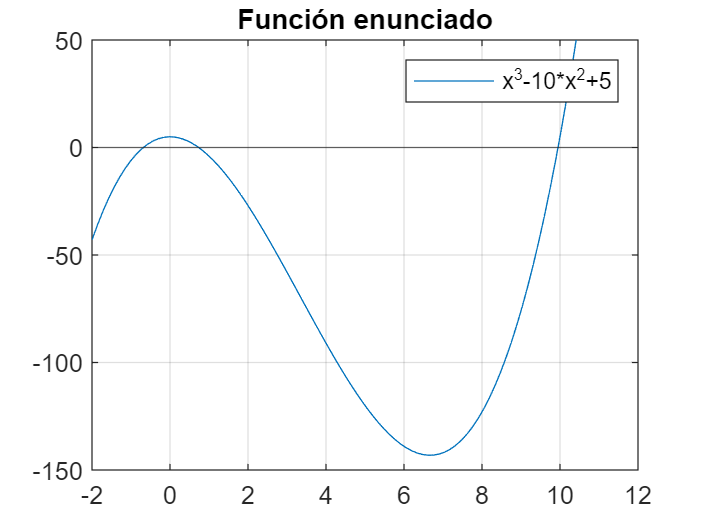

x = linspace(-2, 12);
plot(x, f(x))
hold on
yline(0)
ylim([-150, 50])
xlim([-2, 12])
legend('x^{3}-10*x^{2}+5')
title("Función enunciado")
grid
hold off

A continuación, se halla las raíces del polinomio con el comando `roots.`

sol_matlab = sort(roots(p));
% Se convierte en tabla los datos obtenidos
tabla_sol_matlab = array2table(sol_matlab, 'VariableNames', "SOLUCIONES MATLAB");
disp("Las soluciones que da matlab son:")

Las soluciones que da matlab son:


disp(tabla_sol_matlab)

    SOLUCIONES MATLAB
    _________________

        -0.68409     
          0.7346     
          9.9495     



Para obtener los intervalos se usa la función `raices.`

x = raices(f, -0.7, 10, dx);
% Se borra los NaN de la matriz de intervalos
x = rmmissing(x);
% Se convierte los datos obtenido en tabla
tabla_intervalos = array2table(x);
disp("Con la función raices se han encontrado los siguientes intervalos (x1, x2)")

Con la función raices se han encontrado los siguientes intervalos (x1, x2)


disp(tabla_intervalos)

      x1        x2  
    ______    ______

    -0.685    -0.684
     0.734     0.735
     9.949      9.95



Con la función `bisección `calculamos las soluciones aproximadas en los intervalos obtenidos.

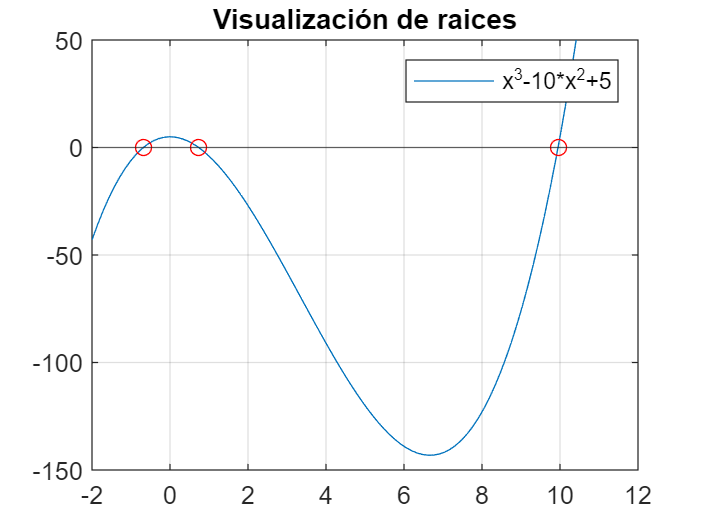

% Tamaño del vector de las raíces
n = size(sol_matlab);
sol_biseccion = zeros(n);
error_rel = zeros(n);
error_biseccion = 1e-3;
% Este bucle usa la función biseccion para hallar las raíces  a la vez que se haya el error relativo 
for i = 1: n
    sol_biseccion(i)= biseccion(f,x(i,1),x(i,2), error_biseccion) ;  
    error_rel(i) = abs((sol_matlab(i)- sol_biseccion(i))/sol_matlab(i))*100;
end
% Dibujamos las soluciones obtenidas
x = linspace(-2, 12);
plot(x, f(x))
hold on
yline(0)
plot(sol_biseccion, f(sol_biseccion), 'ro')
ylim([-150, 50])
xlim([-2, 12])
legend('x^{3}-10*x^{2}+5')
title("Visualización de raices")
grid
hold off

% Se crea una tabla para mostrar el resultado final
tabla_resultados = table(sol_biseccion, sol_matlab, num2str(error_rel, '%.4f %%'),'VariableNames',["SOLUCIÓN APROXIMADA",'SOLUCIÓN MATLAB',"ERROR (%)"]);
disp("Resultados obtenidos:")

Resultados obtenidos:


disp(tabla_resultados)

    SOLUCIÓN APROXIMADA    SOLUCIÓN MATLAB    ERROR (%)
    ___________________    _______________    _________

         -0.68412             -0.68409        0.0044 % 
          0.73463               0.7346        0.0029 % 
           9.9495               9.9495        0.0001 % 

